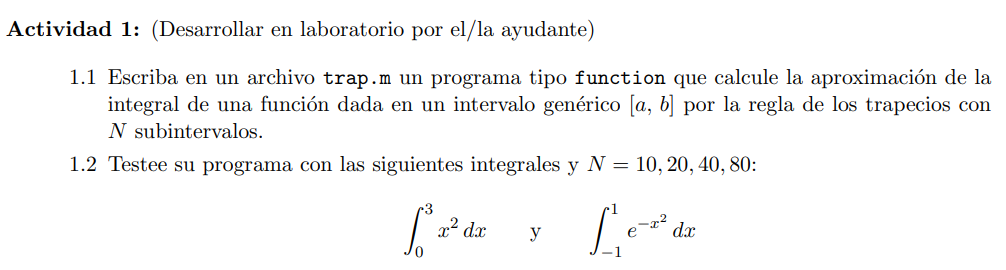

**Item 2**

format long
N=[10,20,40,80];
ytrap1=zeros(1,4);
ytrap2=zeros(1,4);
ysimp1=zeros(1,4);
ysimp2=zeros(1,4);

Primero calcularemos unas aproximacion a la siguiente integral


$$\int_0^3 x^2dx$$


f = @(x) x.^2;
% Aproximacion por regla del trapecio
ytrap1(1)=trapecios(f,0,3,N(1));
ytrap1(2)=trapecios(f,0,3,N(2));
ytrap1(3)=trapecios(f,0,3,N(3));
ytrap1(4)=trapecios(f,0,3,N(4));
%Aproximacion por regla de simpson
ysimp1(1)=simpson(f,0,3,N(1));
ysimp1(2)=simpson(f,0,3,N(2));
ysimp1(3)=simpson(f,0,3,N(3));
ysimp1(4)=simpson(f,0,3,N(4));

Notar que 


$$\int_0^3x^2dx=9$$


%Valor exacto
yexac1=9*ones(1,4);

Creamos una tabla con los valores aproximados por los metodos de trapecios y simpson compuestos, junto con los valores exactos

%Tabla
T1 = table();
T1.Iteracion = N';
T1.Trapecios = ytrap1';
T1.Simpson = ysimp1';
T1.Exacta = yexac1';
disp(T1)

    Iteracion       Trapecios        Simpson    Exacta
    _________    ________________    _______    ______

       10        9.05555555555556       9         9   
       20        9.01246537396122       9         9   
       40        9.00295857988166       9         9   
       80        9.00072103829515       9         9   



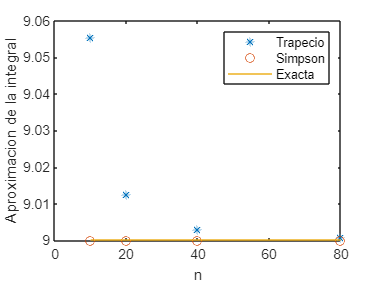

plot(N,ytrap1,'*',N,ysimp1,'o',N,yexac1,'-'); xlabel('n'); ylabel('Aproximacion de la integral');
legend('Trapecio','Simpson','Exacta')

A continuacion vamos a calcular una aproximacion a la siguiente integral


$$\int_{-1}^1 e^{-x^2}$$


g = @(x) exp(-x.^2);
% Aproximacion por regla del trapecio
ytrap2(1)=trapecios(g,-1,1,N(1));
ytrap2(2)=trapecios(g,-1,1,N(2));
ytrap2(3)=trapecios(g,-1,1,N(3));
ytrap2(4)=trapecios(g,-1,1,N(4));
%Aproximacion por regla de simpson
ysimp2(1)=simpson(g,-1,1,N(1));
ysimp2(2)=simpson(g,-1,1,N(2));
ysimp2(3)=simpson(g,-1,1,N(3));
ysimp2(4)=simpson(g,-1,1,N(4));

Notar que 


$$\int_{-1}^1e^{-x^2}dx=\sqrt\pi erf(1)$$


%Valor exacto
yexac2=sqrt(pi)*erf(1)*ones(1,4);

Creamos una tabla con los valores aproximados por los metodos de trapecios y simpson compuestos, junto con los valores exactos

%Tabla
T2 = table();
T2.Iteracion = N';
T2.Trapecios = ytrap2';
T2.Simpson = ysimp2';
T2.Exacta = yexac2';
disp(T2)

    Iteracion       Trapecios            Simpson              Exacta     
    _________    ________________    ________________    ________________

       10        1.48758269401933    1.49365074976068    1.49364826562485
       20        1.49228902188511    1.49364839100166    1.49364826562485
       40        1.49332574825819    1.49364827269122    1.49364826562485
       80        1.49356966982283    1.49364826604461    1.49364826562485



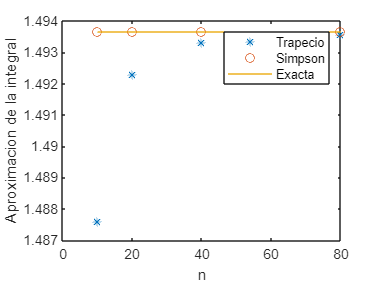

plot(N,ytrap2,'*',N,ysimp2,'o',N,yexac2,'-'); xlabel('n'); ylabel('Aproximacion de la integral');
legend('Trapecio','Simpson','Exacta')